# A pitch/plunge aeroelastic system: Active Flutter Control

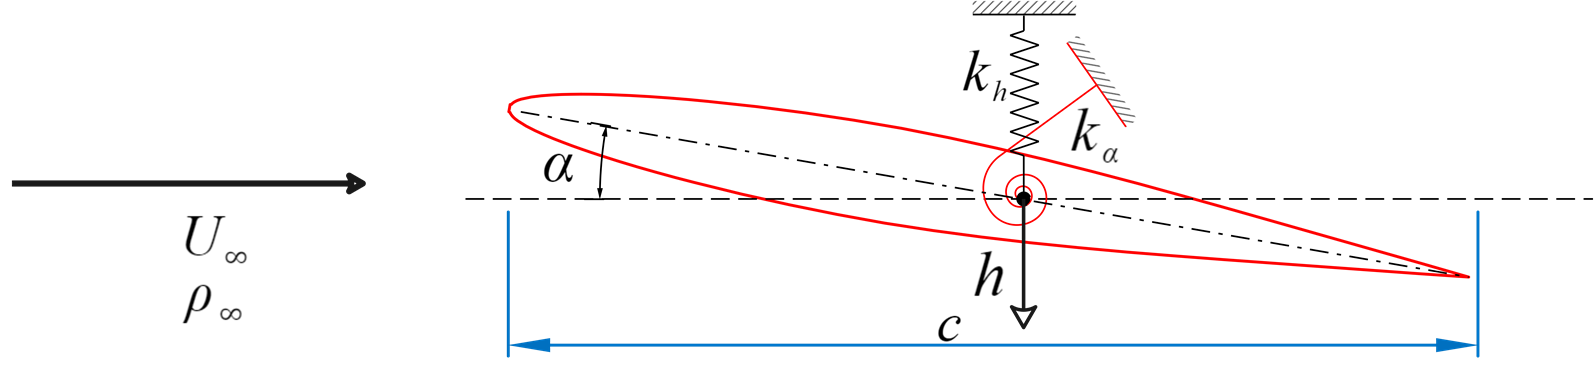

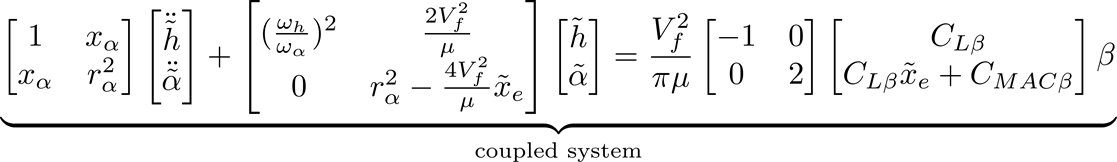

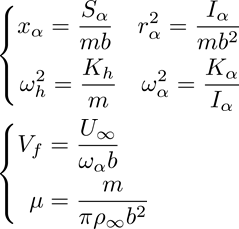

clc; clear; close all;

## Step 1: Structural parameters: 

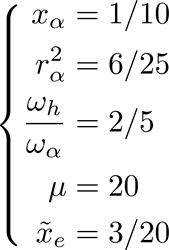

%% nondimensional parameters: 
ra2 = 6/25 ; 
mu = 20 ; 
xe = 3/20 ; 
xa = 1/10 ; 
wha = 2/5 ;

## Step 2: Aerodynamic modelling for an airfoil with variable flap : linear approximation 

-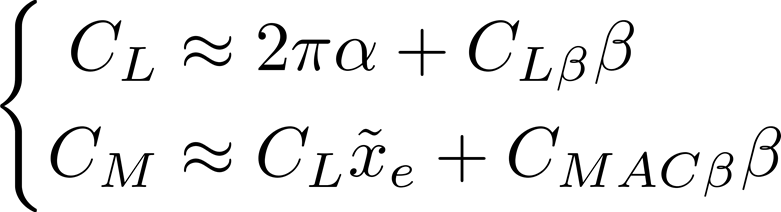

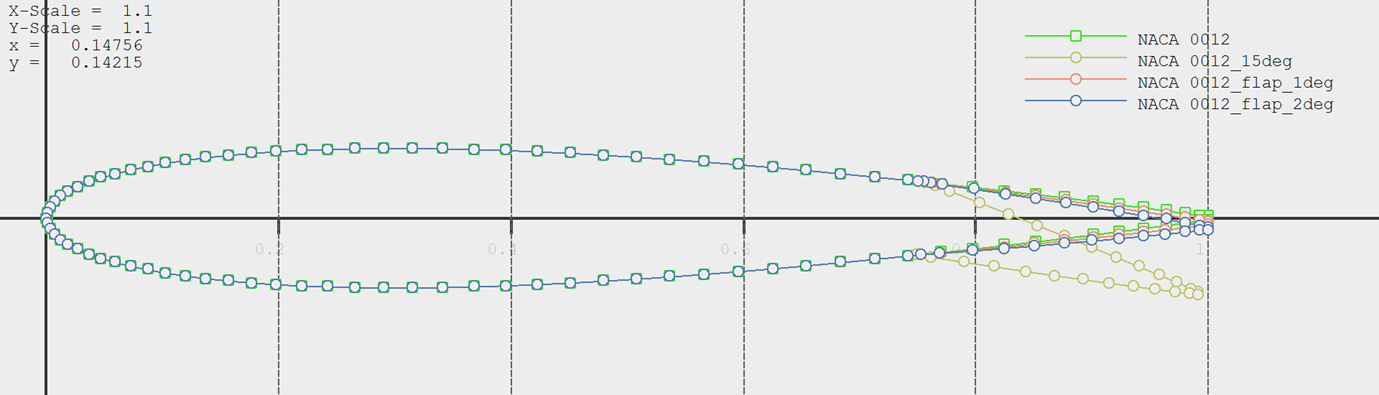

%% control surface aerodynamic derivatives 

Clb = 3.954 ; 
Cmb = -0.6303 ; 

## Step 3: Aeroservoelastic system: 

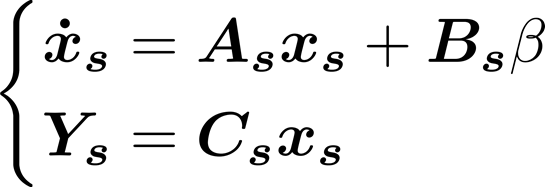

%% state feedback law design at Vf = 2.0 
V_test = 2; 

V = V_test ; 

%% structural EOM: left hand side term 
Ms = [1 xa ; xa ra2] ;
Ks = [wha^2  2*V^2/mu ; 0 ra2 - 4*xe*V^2/mu] ; 
Ie = eye(2); 

As = [zeros(2) Ie; -Ms\Ks zeros(2)] ; 

%% Structural EOM: right hand side term, control surface 
Ts = V^2/pi/mu*[-1 0;0 2]*[Clb;Clb*xe + Cmb]; 
Bs = [zeros(2,1);Ms\Ts];

## Step 4: control system design: optimal gain *K* 

%% LQR for optimal gain 
Q = eye(size(As,1));    %Q, R matrices are adjustable 
R =100;  
[Kc,Rc,Ec]=lqr(As,Bs,Q,R);

et = eig(As);    % open-loop eigenvalues 
etc = eig(As-Bs*Kc);  % closed-loop eigenvalues

## Step 5: Structural response: initial condition response 

%% initial condition response 

Cs = eye(4);    % state-to-output matrix

sys_cl = ss(As-Bs*Kc,[],Cs,[]);  % closed-loop system 
sys_op = ss(As,[],Cs,[]);        % open-loop system 

x0=[0 1e-2 0 0]';   % initial condition 

[y_cl,t_cl] = initial(sys_cl,x0,200);   % initial condition response 
[y_op,t_op] = initial(sys_op,x0,200);

## Step 6: postprocessing: plot the response 

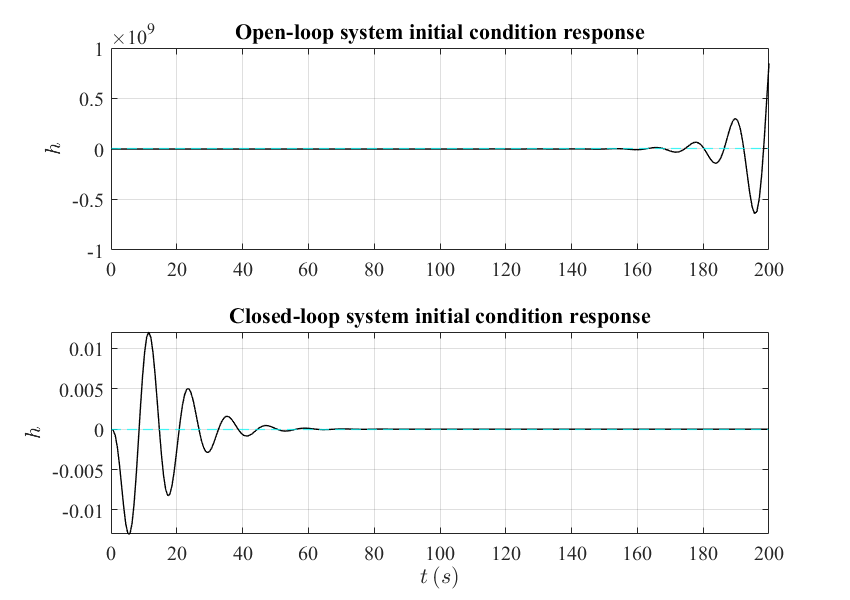

%% postprocessing 
figure1 = figure('Color',[1 1 1]);
set(gcf,'Position',[300,50,850,600]);
subplot(2,1,1); 
plot(t_op,y_op(:,1),'k-','linewidth',1); 

title('Open-loop system initial condition response')

set(gca,'Fontname','Times New Roman');
set(gca,'FontSize',15);
set(gca,'XLim',[0 200],'XTick',0:20:200);
% set(gca,'YLim',[-10 2],'YTick',-10:2:2);
yline(0,'c--','linewidth',1);
ylabel('$h$','Interpreter','latex') 
% xlabel('$t \thinspace (s)$','Interpreter','latex') 
grid on 
box on; 

%
subplot(2,1,2); 
plot(t_cl,y_cl(:,1),'k-','linewidth',1); 

title('Closed-loop system initial condition response')

set(gca,'Fontname','Times New Roman');
set(gca,'FontSize',15);
set(gca,'XLim',[0 200],'XTick',0:20:200);
% set(gca,'YLim',[-10 2],'YTick',-10:2:2);
yline(0,'c--','linewidth',1);
ylabel('$h$','Interpreter','latex') 
xlabel('$t \thinspace (s)$','Interpreter','latex') 
grid on 
box on; 

## Step 7: Linear stability analysis: Eigenvalues 

%% solve the eigenvalues for a range of velocities  
V_test = 0.1:0.025:3 ; 

%% create a figure 
figure2 = figure('Color',[1 1 1]);
set(gcf,'Position',[300,50,850,600]);
hold on; 
%% 

for i=1:size(V_test,2)

V = V_test(i) ; 

Ms = [1 xa ; xa ra2] ;
Ks = [wha^2  2*V^2/mu ; 0 ra2 - 4*xe*V^2/mu] ; 
Ie = eye(2); 

As = [zeros(2) Ie; -Ms\Ks zeros(2)] ; 

%% control surface 
Ts = V^2/pi/mu*[-1 0;0 2]*[Clb;Clb*xe + Cmb]; 
Bs = [zeros(2,1);Ms\Ts];

%%  eigenvalues 
lambda_op = eig(As);    % open-loop system 
lambda_cl = eig(As-Bs*Kc); % closed-loop system 

h1 = plot(V, real(lambda_op),'ro'); 
h2 = plot(V, real(lambda_cl),'ro','MarkerFaceColor','g'); 
end 



#### Postprocessing: plot the eigenvalues in complex plane 

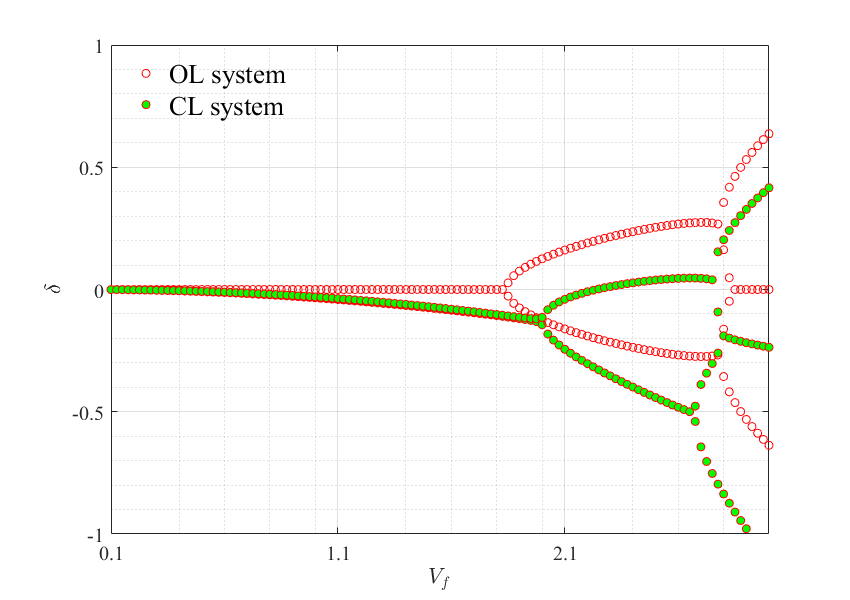

[ht,b]=legend([h1(1) h2(1)],{'OL system','CL system'} ,'Location','northwest',...
     'FontSize',20,'TextColor','black','FontName','Times New Roman'); 
set(findobj(b,'-property','MarkerSize'),'MarkerSize',15)
legend boxoff
%%
set(gca,'Fontname','Times New Roman');
set(gca,'FontSize',15);
set(gca,'XLim',[0.1 3],'XTick',0.1:1:3);
set(gca,'YLim',[-1. 1.],'YTick',-1.5:0.5:1.5);

ylabel('$\delta$','Interpreter','latex') 
xlabel('$V_f$','Interpreter','latex') 
grid on 
grid minor
box on; 